
clear; clc; close all;


%  SECTION 1 — SYSTEM PARAMETERS

% --- OFDM grid ---
N_sc  = 72;     % Active subcarriers
N_fft = 128;    % FFT size (smallest power of 2 above 72)
N_sym = 14;     % OFDM symbols per slot

% SCS = 15 kHz
fs  = 1.92e6;           % Sample rate [Hz]  (= N_fft * SCS)
Ts  = 1 / fs;           % Sample period     = 520.83 ns
SCS = fs / N_fft;       % Subcarrier spacing = 15 000 Hz 

% Cyclic prefix
%  Need T_cp > max(offset_list) = 20 us
CP_len = 40;
T_cp   = CP_len * Ts;            % 20.833 us
T_sym  = (N_fft + CP_len) * Ts;  % 87.500 us total symbol duration

%  Bins 1..72 hold the active subcarriers; bins 73..128 are guard/unused.
fft_bin_idx = 1:N_sc;   % 1x72 row vector

% 0-based bin index vector, used in H_true and R_freq
k_vec = (0:N_sc-1).';   % 72x1 column vector  (k_vec(m) = m-1)

% --- Pilots ---
pilot_spacing = 3;
pilot_idx     = 1:pilot_spacing:N_sc;   % 1,4,7,...,70  -> 24 pilots
N_pilots      = length(pilot_idx);
tau_max_alias = 1 / (pilot_spacing * SCS);   % 22.22 us

% --- parameters ---
doppler_list = [0, 500, 1000, 2500, 5000];   % [Hz]
offset_list  = [0, 5e-6, 10e-6, 20e-6];      % [s]
SNR_dB_vec   = -10:1:20;                      % [dB]
num_iter     = 200;                            % Monte Carlo iterations per point

n_dop = length(doppler_list);
n_off = length(offset_list);
n_snr = length(SNR_dB_vec);

% Reference indices for the fixed-parameter plots
idx_fd5000 = find(doppler_list == 5000);
idx_dt20   = find(offset_list  == 20e-6);


% Section-2 => PRECOMPUTE MMSE WEIGHT MATRICES

Precomputing MMSE matrices...




dk_mat = k_vec - k_vec.';   % 72x72, broadcast: (72x1) - (1x72)

W_MMSE_store = cell(n_off, n_snr);
R_ff_store   = zeros(N_sc, N_sc, n_off);  % R_ff is correlation among data subcarriers
R_fp_store   = zeros(N_sc, N_pilots, n_off); % R-fp is correlation between pilots and data subcarriers
R_pp_store   = zeros(N_pilots, N_pilots, n_off); % R-pp is correlation among pilots
MSE_MMSE_th  = zeros(n_off, n_snr);     % theoretical 

for i_off = 1:n_off
    tau = offset_list(i_off);

    % Frequency correlation matrix
    R_ff = exp(-1j * 2*pi * dk_mat * SCS * tau);   % N_sc x N_sc
    R_fp = R_ff(:, pilot_idx);                       % N_sc   x N_pilots
    R_pp = R_ff(pilot_idx, pilot_idx);               % N_pilots x N_pilots

    R_ff_store(:,:,i_off) = R_ff;
    R_fp_store(:,:,i_off) = R_fp;
    R_pp_store(:,:,i_off) = R_pp;

    for i_snr = 1:n_snr
        sigma2 = 10^(-SNR_dB_vec(i_snr) / 10);

        % MMSE weight matrix
        W_MMSE_store{i_off, i_snr} = R_fp / (R_pp + sigma2 * eye(N_pilots));

        % Theoretical MMSE MSE lower bound
        E_cov = R_ff - R_fp / (R_pp + sigma2 * eye(N_pilots)) * R_fp';
        MSE_MMSE_th(i_off, i_snr) = real(trace(E_cov)) / N_sc;
    end
end


Done. (4 offset x 31 SNR combinations)





  % Section-3 => RESULT ARRAYS


MSE_LS   = zeros(n_dop, n_off, n_snr);
MSE_MMSE = zeros(n_dop, n_off, n_snr);


%   Section-4 => MONTE CARLO SIMULATION LOOP


Starting Monte Carlo simulation (200 iter/point)...




total_combos = n_dop * n_off;
combo = 0;

for i_dop = 1:n_dop
    fd = doppler_list(i_dop);

    for i_off = 1:n_off
        tau   = offset_list(i_off);
        n_tau = round(tau / Ts);   % integer samples; 

        combo = combo + 1;
       
        for i_snr = 1:n_snr
            sigma2     = 10^(-SNR_dB_vec(i_snr) / 10);
            W_MMSE_now = W_MMSE_store{i_off, i_snr};

            acc_ls   = 0;
            acc_mmse = 0;

            for mc_iter = 1:num_iter

                
                %  BLOCK 1 — SIGNAL GENERATOR
                %  QPSK resource grid -> OFDM modulation (IFFT + CP)
          

                % QPSK data symbols (average power = 1)
                data_idx = randi([0 3], N_sc, N_sym);
                tx_grid  = exp(1j * (pi/4 + pi/2 * data_idx));

                % Insert known pilot symbols (value = +1, BPSK)
                tx_grid(pilot_idx, :) = 1;

                % OFDM modulation: normalized IFFT, add CP
                tx_time = zeros(N_fft + CP_len, N_sym);
                for sym = 1:N_sym
                    X_fft              = zeros(N_fft, 1);
                    X_fft(fft_bin_idx) = tx_grid(:, sym);          % bins 1..72
                    x_ifft             = ifft(X_fft, N_fft) * sqrt(N_fft);
                    cp                 = x_ifft(end - CP_len + 1 : end);
                    tx_time(:, sym)    = [cp; x_ifft];
                end

                % Block-2 - CHANNEL
                %  Doppler: sample-by-sample in time domain
                %  Time offset: circular shift of n_tau samples
                
                rx_time = zeros(N_fft + CP_len, N_sym);
                H_true  = zeros(N_sc, N_sym);

                for sym = 1:N_sym
                    % Absolute start time of this CP+symbol buffer
                    t_start = (sym - 1) * T_sym;
                    t_vec   = t_start + (0 : N_fft + CP_len - 1).' * Ts;

                    % Doppler: multiply each sample by its phase rotation
                    tx_dop = tx_time(:, sym) .* exp(1j * 2*pi * fd * t_vec);

                    % Integer time offset: circular shift within CP guard
                    rx_time(:, sym) = circshift(tx_dop, n_tau);

                    % Analytical H_true
                    %  Evaluate Doppler at midpoint of the FFT window
                    
                    t_mid     = t_start + (CP_len + N_fft/2 - 0.5) * Ts;
                    dop_phase = exp(1j * 2*pi * fd * t_mid);   % scalar

                    %  Phase ramp from integer shift n_tau, using 0-based bin index:
                    %  H[m] = exp(-j*2*pi*(m-1)*n_tau/N_fft)
                    %  With one-sided mapping bin_m = m, so (bin_m-1) = (m-1) = k_vec(m)
                    time_ramp = exp(-1j * 2*pi * k_vec * n_tau / N_fft);   % 72x1

                    H_true(:, sym) = dop_phase * time_ramp;
                end

                % Add AWGN (signal power = 1 by construction of QPSK + sqrt(N_fft) IFFT)
                noise   = sqrt(sigma2/2) * (randn(N_fft + CP_len, N_sym) + ...
                                            1j*randn(N_fft + CP_len, N_sym));
                rx_noisy = rx_time + noise;

                 % Block-3 - RECEIVER
                %  Remove CP -> FFT -> extract subcarriers -> estimate H

                % Remove CP and take FFT (normalized)
                rx_fft_full = fft(rx_noisy(CP_len+1:end, :), N_fft) / sqrt(N_fft);

                % Extract the 72 active subcarriers (bins 1..72)
                rx_obs = rx_fft_full(fft_bin_idx, :);   % N_sc x N_sym

                % ---- LS Estimator ----
                %  H_LS[pilot] = rx_obs[pilot] / X[pilot]
                %  Since X[pilot] = 1, H_LS[pilot] = rx_obs[pilot] directly.
                %  Full grid recovered by linear interpolation per symbol

                H_ls = zeros(N_sc, N_sym);
                for sym = 1:N_sym
                    H_ls_p   = rx_obs(pilot_idx, sym) ./ tx_grid(pilot_idx, sym);
                    H_ls(:, sym) = interp1(pilot_idx.', H_ls_p, (1:N_sc).', ...
                                           'linear', 'extrap');
                end

                % ---- MMSE Estimator ----
                %  H_MMSE = W_MMSE * H_LS_pilots
                %  W_MMSE = R_fp * (R_pp + sigma2*I)^{-1}  [pre-computed]
                H_mmse = zeros(N_sc, N_sym);
                for sym = 1:N_sym
                    H_ls_p      = rx_obs(pilot_idx, sym) ./ tx_grid(pilot_idx, sym);
                    H_mmse(:, sym) = W_MMSE_now * H_ls_p;
                end

                % ---- Accumulate MSE ----
                acc_ls   = acc_ls   + mean(abs(H_ls   - H_true).^2, 'all');
                acc_mmse = acc_mmse + mean(abs(H_mmse - H_true).^2, 'all');

            end  % Monte Carlo

            MSE_LS  (i_dop, i_off, i_snr) = acc_ls   / num_iter;
            MSE_MMSE(i_dop, i_off, i_snr) = acc_mmse / num_iter;

        end  % SNR
    end  % offset
end  % Doppler

  [ 1/20]  fd=    0 Hz | tau=  0.0 us | n_tau= 0 samples
  [ 2/20]  fd=    0 Hz | tau=  5.0 us | n_tau=10 samples
  [ 3/20]  fd=    0 Hz | tau= 10.0 us | n_tau=19 samples
  [ 4/20]  fd=    0 Hz | tau= 20.0 us | n_tau=38 samples
  [ 5/20]  fd=  500 Hz | tau=  0.0 us | n_tau= 0 samples
  [ 6/20]  fd=  500 Hz | tau=  5.0 us | n_tau=10 samples
  [ 7/20]  fd=  500 Hz | tau= 10.0 us | n_tau=19 samples
  [ 8/20]  fd=  500 Hz | tau= 20.0 us | n_tau=38 samples
  [ 9/20]  fd= 1000 Hz | tau=  0.0 us | n_tau= 0 samples
  [10/20]  fd= 1000 Hz | tau=  5.0 us | n_tau=10 samples
  [11/20]  fd= 1000 Hz | tau= 10.0 us | n_tau=19 samples
  [12/20]  fd= 1000 Hz | tau= 20.0 us | n_tau=38 samples
  [13/20]  fd= 2500 Hz | tau=  0.0 us | n_tau= 0 samples
  [14/20]  fd= 2500 Hz | tau=  5.0 us | n_tau=10 samples
  [15/20]  fd= 2500 Hz | tau= 10.0 us | n_tau=19 samples
  [16/20]  fd= 2500 Hz | tau= 20.0 us | n_tau=38 samples
  [17/20]  fd= 5000 Hz | tau=  0.0 us | n_tau= 0 samples
  [18/20]  fd= 5000 Hz | tau=  


Simulation complete.



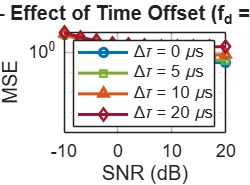


%  Section-5 => PLOTS

clr_off = [0.00 0.45 0.74; 0.47 0.67 0.19; 0.85 0.33 0.10; 0.64 0.08 0.18];
clr_dop = [0.30 0.30 0.30; 0.00 0.45 0.74; 0.47 0.67 0.19; 0.85 0.33 0.10; 0.64 0.08 0.18];
mk_off  = {'o','s','^','d'};
mk_dop  = {'o','s','^','d','p'};
lw = 1.8; ms = 5; lbl_off = arrayfun(@(x) sprintf('\\Delta\\tau = %g \\mus',x*1e6), offset_list,  'UniformOutput',false);
lbl_dop = arrayfun(@(x) sprintf('f_d = %d Hz', x),                                  doppler_list, 'UniformOutput',false);

% Helper: create a standard axes
new_ax = @(pos) axes(figure('Color','w','Position',pos));  

% Fig 1 — LS: time offset sweep (fd = 5000 Hz)
ax1 = new_ax([50  550 620 460]); hold on; grid on; box on;
set(ax1,'YScale','log','FontSize',11,'GridAlpha',0.3);
for i = 1:n_off,  semilogy(ax1,SNR_dB_vec,squeeze(MSE_LS(idx_fd5000,i,:)),'Color',clr_off(i,:),'LineWidth',lw,'Marker',mk_off{i},'MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName',lbl_off{i}); end
xlabel('SNR (dB)'); ylabel('MSE'); title('LS — Effect of Time Offset (f_d = 5000 Hz)','FontWeight','bold'); legend('Location','southwest'); xlim([SNR_dB_vec(1) SNR_dB_vec(end)]); ylim([1e-4 10]);

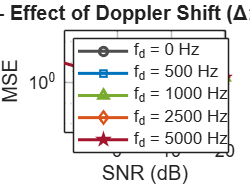


% Fig 2 — LS: Doppler sweep (tau = 20 us)
ax2 = new_ax([700 550 620 460]); hold on; grid on; box on;
set(ax2,'YScale','log','FontSize',11,'GridAlpha',0.3);
for i = 1:n_dop, semilogy(ax2,SNR_dB_vec,squeeze(MSE_LS(i,idx_dt20,:)),  'Color',clr_dop(i,:),'LineWidth',lw,'Marker',mk_dop{i},'MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName',lbl_dop{i}); end
xlabel('SNR (dB)'); ylabel('MSE'); title('LS — Effect of Doppler Shift (\Delta\tau = 20 \mus)','FontWeight','bold'); legend('Location','southwest'); xlim([SNR_dB_vec(1) SNR_dB_vec(end)]); ylim([1e-4 10]);

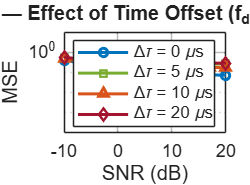


% Fig 3 — MMSE: time offset sweep (fd = 5000 Hz)
ax3 = new_ax([50  50  620 460]); hold on; grid on; box on;
set(ax3,'YScale','log','FontSize',11,'GridAlpha',0.3);
for i = 1:n_off,  semilogy(ax3,SNR_dB_vec,squeeze(MSE_MMSE(idx_fd5000,i,:)),'Color',clr_off(i,:),'LineWidth',lw,'Marker',mk_off{i},'MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName',lbl_off{i}); end
xlabel('SNR (dB)'); ylabel('MSE'); title('MMSE — Effect of Time Offset (f_d = 5000 Hz)','FontWeight','bold'); legend('Location','southwest'); xlim([SNR_dB_vec(1) SNR_dB_vec(end)]); ylim([1e-4 10]);

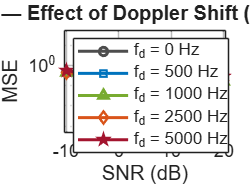


% Fig 4 — MMSE: Doppler sweep (tau = 20 us)
ax4 = new_ax([700 50  620 460]); hold on; grid on; box on;
set(ax4,'YScale','log','FontSize',11,'GridAlpha',0.3);
for i = 1:n_dop, semilogy(ax4,SNR_dB_vec,squeeze(MSE_MMSE(i,idx_dt20,:)), 'Color',clr_dop(i,:),'LineWidth',lw,'Marker',mk_dop{i},'MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName',lbl_dop{i}); end
xlabel('SNR (dB)'); ylabel('MSE'); title('MMSE — Effect of Doppler Shift (\Delta\tau = 20 \mus)','FontWeight','bold'); legend('Location','southwest'); xlim([SNR_dB_vec(1) SNR_dB_vec(end)]); ylim([1e-4 10]);

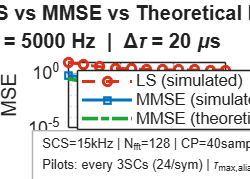


% Fig 5 — LS vs MMSE vs Theoretical bound (fd=5000Hz, tau=20us)
ax5 = new_ax([375 270 700 500]); hold on; grid on; box on;
set(ax5,'YScale','log','FontSize',11,'GridAlpha',0.3);
semilogy(ax5,SNR_dB_vec,squeeze(MSE_LS  (idx_fd5000,idx_dt20,:)),'Color',[0.85 0.20 0.10],'LineStyle','--','LineWidth',lw,'Marker','o','MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName','LS (simulated)');
semilogy(ax5,SNR_dB_vec,squeeze(MSE_MMSE(idx_fd5000,idx_dt20,:)),'Color',[0.00 0.45 0.74],'LineStyle','-', 'LineWidth',lw,'Marker','s','MarkerSize',ms,'MarkerIndices',1:3:n_snr,'DisplayName','MMSE (simulated)');
semilogy(ax5,SNR_dB_vec,MSE_MMSE_th(idx_dt20,:),                 'Color',[0.10 0.65 0.20],'LineStyle','-.','LineWidth',lw+0.4,'DisplayName','MMSE (theoretical bound)');
xlabel('SNR (dB)'); ylabel('MSE'); title({'LS vs MMSE vs Theoretical Bound','f_d = 5000 Hz  |  \Delta\tau = 20 \mus'},'FontWeight','bold'); legend('Location','southwest'); xlim([SNR_dB_vec(1) SNR_dB_vec(end)]); ylim([1e-5 10]);
annotation(ax5.Parent,'textbox',[0.13 0.15 0.46 0.12],'String', ...
    {sprintf('SCS=%dkHz | N_{fft}=%d | CP=%dsamples=%.3f\\mus',SCS/1e3,N_fft,CP_len,T_cp*1e6), ...
     sprintf('Pilots: every %dSCs (%d/sym) | \\tau_{max,alias}=%.1f\\mus',pilot_spacing,N_pilots,tau_max_alias*1e6)}, ...
    'FontSize',8,'BackgroundColor','w','EdgeColor',[0.7 0.7 0.7],'FitBoxToText','on');